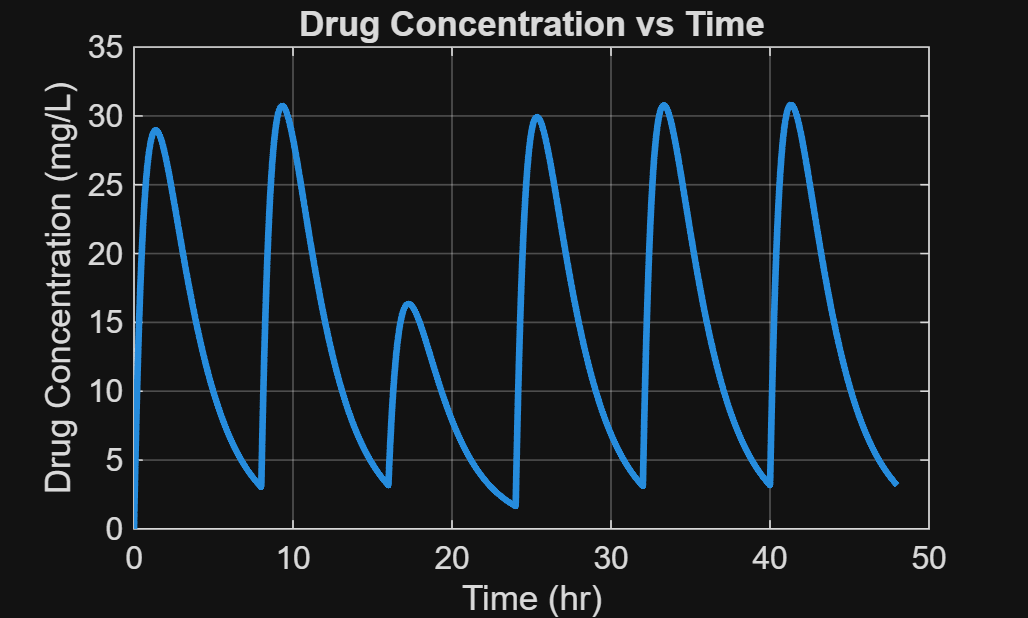

clc; clear; close all;

% Parameters
ka = 1.2;          % absorption rate (1/hr)
ke = 0.4;          % elimination rate (1/hr)
V  = 20;           % volume (L)

Dose = 500;        % mg per dose
tau = 8;           % dosing interval (hr)

t_end = 48;        % total simulation time (hr)
dt = 0.01;

% Time vector
t = 0:dt:t_end;

% Initialization
A = zeros(size(t));   % drug in gut
C = zeros(size(t));   % concentration

% Initial dose
A(1) = Dose;

% Simulation loop
for i = 1:length(t)-1
    
    % Add repeated doses
    if mod(t(i), tau) < dt
        A(i) = A(i) + Dose;
    end
    
    % Differential equations
    dA = -ka * A(i);
    dC = (ka * A(i))/V - ke * C(i);
    
    % Euler update
    A(i+1) = A(i) + dA*dt;
    C(i+1) = C(i) + dC*dt;
end

% Plot
figure;
plot(t, C, 'LineWidth', 2);
xlabel('Time (hr)');
ylabel('Drug Concentration (mg/L)');
title('Drug Concentration vs Time');
grid on;